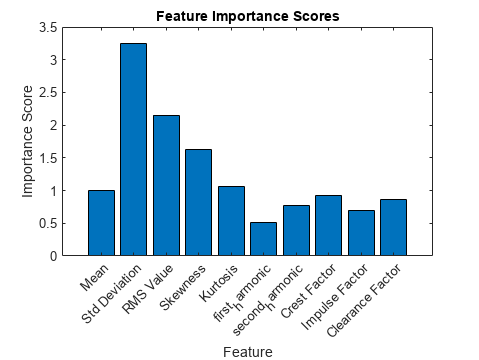

clc;
clear;

% Load training data and labels
train_data_x = load('data_train.mat');
train_data_y = load('data_train_labels.mat');

% Extracting the actual data from the loaded variables
train_data_x = train_data_x.data_train;
train_data_y = train_data_y.data_train_labels;

% Define label names
label_names = {'normal', 'roller', 'inner', 'outer', ...
               'inner+roller', 'outer+inner', 'outer+inner+roller', 'outer+roller'};

% Use 'data_train_labels' as your target labels
target_labels = train_data_y';

% Preallocate feature matrix
num_columns = numel(train_data_x);
num_features = 10; % Including mean, std, rms, skewness, kurtosis, 1st harmonic, 2nd harmonic, crest factor, impulse factor, and clearance factor
time_domain_features = zeros(num_columns, num_features);


% Compute and populate the time domain feature matrix
for col = 1:num_columns
    data = train_data_x{col};
    mean_value = mean(data);
    std_deviation = std(data);
    rms_value = rms(data);
    skewness_value = skewness(data);
    kurtosis_value = kurtosis(data);
    fft_data = fft(data);
    N = length(data);
    fft_normalized = abs(fft_data/N);
    first_order_harmonic = fft_normalized(2);
    second_order_harmonic = fft_normalized(3);
    crest_factor = max(data) / rms_value;
    impulse_factor = max(data) / mean(abs(data));
    clearance_factor = max(data) / (max(data) - min(data));
    time_domain_features(col, :) = [mean_value, std_deviation, rms_value, skewness_value, kurtosis_value, first_order_harmonic, second_order_harmonic, crest_factor, impulse_factor, clearance_factor];
end
% Define labels corresponding to the numeric categories
label_names = {'normal', 'roller', 'inner', 'outer', 'inner+roller', 'outer+inner', 'outer+inner+roller', 'outer+roller'};

% Convert numeric target_labels to cell array of strings using label_names
target_labels_cell = cell(size(target_labels));
for i = 1:numel(target_labels)
    target_labels_cell{i} = label_names{target_labels(i)};
end

% Assuming 'time_domain_features' is your feature matrix and 'target_labels' are your labels
% Convert target labels from cells to categorical if needed
target_labels_numeric = grp2idx(target_labels_cell); % Convert to numeric if they are cell strings

% Train a Random Forest model
nTrees = 100; % Example: 100 trees
rfModel = TreeBagger(nTrees, time_domain_features, target_labels_numeric, 'Method', 'classification', 'OOBVarImp', 'On');

% Extract feature importance
featureImportance = rfModel.OOBPermutedVarDeltaError;

% Define your feature names
feature_names = {'Mean', 'Std Deviation', 'RMS Value', 'Skewness', 'Kurtosis', ...
                 'first_harmonic', 'second_harmonic','Crest Factor', 'Impulse Factor', 'Clearance Factor'};

% Visualize feature importance with specific feature names
figure;
bar(featureImportance);
title('Feature Importance Scores');
xlabel('Feature');
ylabel('Importance Score');
xticks(1:length(feature_names));
xticklabels(feature_names); % Use your feature names here
xtickangle(45);


% Prepare SOM data structure
sD = som_data_struct(time_domain_features, 'name', 'Machine Condition Data', 'comp_names', {'Mean', 'Std Deviation', 'RMS Value', 'Skewness', 'Kurtosis','first_order_harmonic', 'second', 'Crest Factor', 'Impulse Factor', 'Clearance Factor'});
sD = som_label(sD, 'add', 1:size(time_domain_features, 1), target_labels_cell);

% Train SOM Model
sMap = som_make(sD);

Determining map size...
 map size [19, 12]
Initialization...
Training using batch algorithm...
Rough training phase...
Training:   0/   0 s
Finetuning phase...
Training:   0/   0 s
Final quantization error: 9.269
Final topographic error:  0.055
Final combined error:  17.938


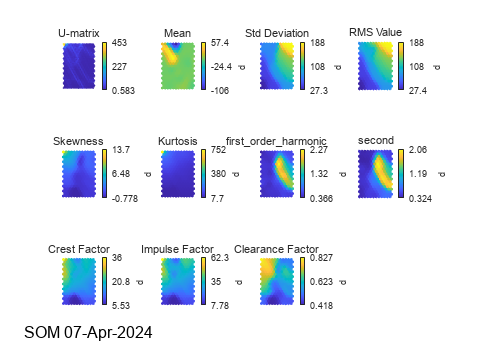


% Calculate pairwise distances between all neurons in the SOM for later use
neuron_distances = pdist2(sMap.codebook, sMap.codebook);

% Automatic labeling of the SOM
sMap = som_autolabel(sMap, sD, 'vote'); % Using 'vote' method for automatic labeling

% Compute u matrix
som_show(sMap);

%% Insert the new logic here to handle unlabeled neurons %%
numNeurons = size(sMap.codebook, 1); % Number of neurons in SOM
labeledIndices = find(~cellfun(@isempty, sMap.labels)); % Indices of labeled neurons
unlabeledIndices = find(cellfun(@isempty, sMap.labels)); % Indices of unlabeled neurons

for i = 1:length(unlabeledIndices)
    currentUnlabeled = unlabeledIndices(i);
    
    % Calculate distances from this unlabeled neuron to all labeled neurons
    distancesToLabeled = neuron_distances(currentUnlabeled, labeledIndices);
    
    % Find the nearest labeled neuron
    [~, minIndex] = min(distancesToLabeled);
    nearestLabeledNeuronIndex = labeledIndices(minIndex);
    
    % Assign the label of the nearest labeled neuron to the current unlabeled neuron
    sMap.labels{currentUnlabeled} = sMap.labels{nearestLabeledNeuronIndex};
end

% Load test data and labels
test_data_x = load('data_test.mat');
test_data_y = load('data_test_labels.mat');

% Extracting the actual data from the loaded variables
test_data_x = test_data_x.data_test;
test_data_y = test_data_y.data_test_labels;

% Preallocate feature matrix for test data
num_test_samples = numel(test_data_x);
test_time_domain_features = zeros(num_test_samples, num_features);
for sample = 1:num_test_samples
    data = test_data_x{sample};
    % Compute features for test data
    mean_value = mean(data);
    std_deviation = std(data);
    rms_value = rms(data);
    skewness_value = skewness(data);
    kurtosis_value = kurtosis(data);
    fft_data = fft(data);
    N = length(data);
    fft_normalized = abs(fft_data/N);
    first_order_harmonic = fft_normalized(2);
    second_order_harmonic = fft_normalized(3);
    crest_factor = max(data) / rms_value;
    impulse_factor = max(data) / mean(abs(data));
    clearance_factor = max(data) / (max(data) - min(data));
    test_time_domain_features(sample, :) = [mean_value, std_deviation, rms_value, skewness_value, kurtosis_value, first_order_harmonic, second_order_harmonic, crest_factor, impulse_factor, clearance_factor];
end

% Find best-matching units (BMUs) for test data on the trained SOM
bmu_indices = som_bmus(sMap, test_time_domain_features);

predicted_labels = cell(length(bmu_indices), 1);
for i = 1:length(bmu_indices)
    predicted_labels{i} = sMap.labels{bmu_indices(i),1}; % Updated to use labels from sMap
end

disp(sMap.labels);

    {'normal'            }
    {'inner'             }
    {'inner'             }
    {'inner'             }
    {'inner'             }
    {'roller'            }
    {'roller'            }
    {'roller'            }
    {'roller'            }
    {'roller'            }
    {'roller'            }
    {'roller'            }
    {'roller'            }
    {'roller'            }
    {'roller'            }
    {'normal'            }
    {'normal'            }
    {'normal'            }
    {'normal'            }
    {'inner'             }
    {'inner'             }
    {'inner'             }
    {'inner'             }
    {'inner'             }
    {'inner'             }
    {'inner'             }
    {'roller'            }
    {'roller'            }
    {'roller'            }
    {'roller'            }
    {'roller'            }
    {'roller'            }
    {'roller'            }
    {'roller'            }
    {'roller'            }
    {'normal'            }
    {'normal'            }
 

% Convert numeric test_data_y to cell array of strings using label_names
actual_labels_cell = cell(size(test_data_y));
for i = 1:numel(test_data_y)
    actual_labels_cell{i} = label_names{test_data_y(i)};
end

for i = 1:length(bmu_indices)
    if ~isempty(sMap.labels{bmu_indices(i),1})
        predicted_labels{i} = sMap.labels{bmu_indices(i),1};
    else
        predicted_labels{i} = 'Unknown'; % Assign a default label if none exists
    end
end


% Compare predicted labels to actual labels
correct_predictions = 0;
for i = 1:length(predicted_labels)
    if strcmp(predicted_labels{i}, actual_labels_cell{i})
        correct_predictions = correct_predictions + 1;
    end
end
    
% Calculate accuracy
accuracy = correct_predictions / length(predicted_labels);
disp(['Accuracy: ', num2str(accuracy * 100), '%']);

Accuracy: 97.8516%


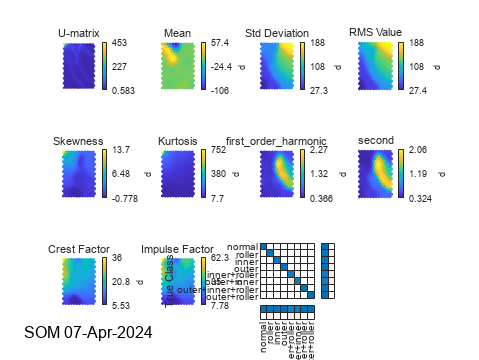

% Convert predicted labels and actual labels to categorical arrays
predicted_labels_cat = categorical(predicted_labels, label_names);
actual_labels_cat = categorical(actual_labels_cell, label_names);

% Display confusion matrix
confusion_chart = confusionchart(actual_labels_cat, predicted_labels_cat, 'RowSummary', 'row-normalized', 'ColumnSummary', 'column-normalized');

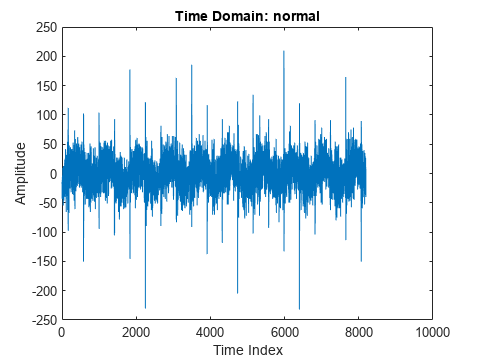

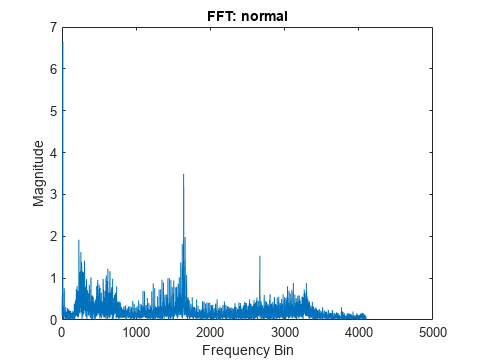

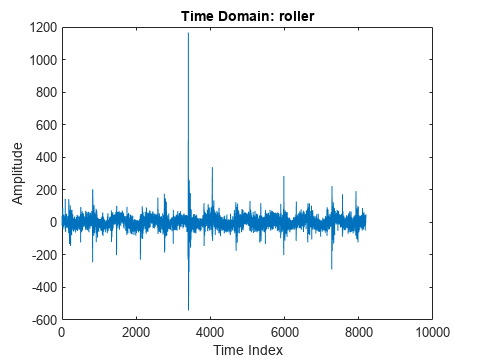

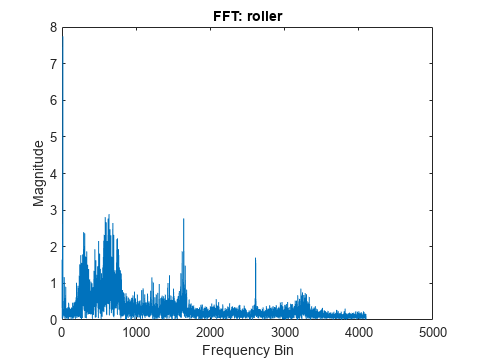

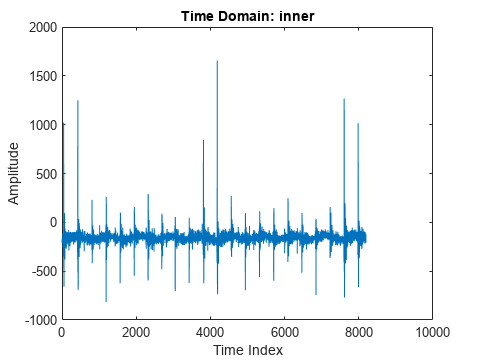

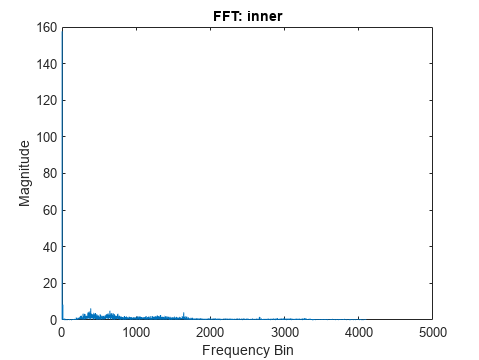

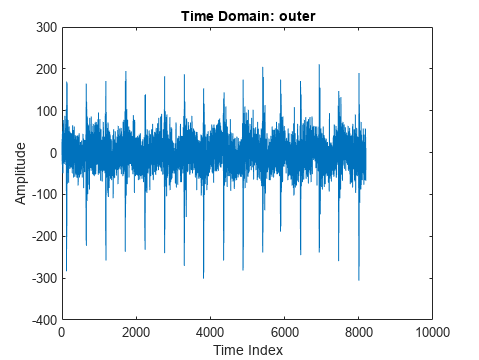

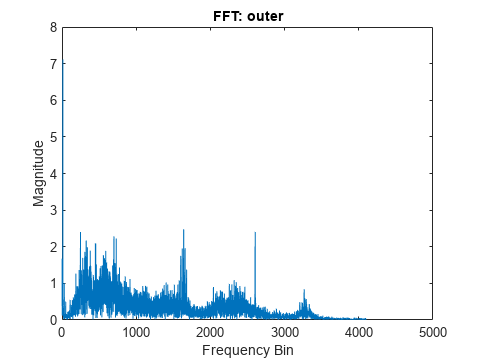

% Loop over each example and plot
% Plot an example of each label's vibration data and FFT
unique_labels = unique(target_labels); % Get unique labels
figure; % Create a new figure

% Preallocate indices for one example per label
example_indices = zeros(1, length(unique_labels));

% Get unique labels
unique_labels = unique(target_labels);

% Find one example index per unique label
example_indices = zeros(1, length(unique_labels));
for i = 1:length(unique_labels)
    example_indices(i) = find(target_labels == unique_labels(i), 1, 'first');
end

% Loop over each example to plot
for i = 1:length(example_indices)
    % Extract the example data
    data_example = train_data_x{example_indices(i)};
    
    % Compute the FFT
    N = length(data_example);
    fft_data = fft(data_example);
    fft_magnitude = abs(fft_data/N);
    
    % Time-domain plot
    figure; % Open a new figure for each plot
    plot(data_example);
    title(['Time Domain: ', label_names{unique_labels(i)}]);
    xlabel('Time Index');
    ylabel('Amplitude');
    
    % FFT plot - Open a new figure for the FFT plot
    figure;
    plot(fft_magnitude(1:N/2+1)); % Plot only the first half of the FFT (the unique part)
    title(['FFT: ', label_names{unique_labels(i)}]);
    xlabel('Frequency Bin');
    ylabel('Magnitude');
end

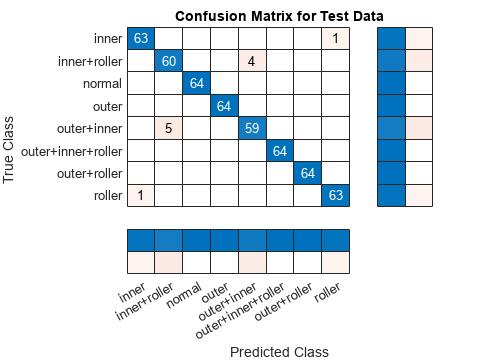

% Assuming predicted_labels and actual_labels_cell are your predicted and actual labels as cell arrays of strings

% Convert cell arrays of strings to categorical for both predicted and actual labels
predicted_labels_cat = categorical(predicted_labels);
actual_labels_cat = categorical(actual_labels_cell);

% Display confusion matrix
confusionMatrixChart = confusionchart(actual_labels_cat, predicted_labels_cat);

% Optional: Improve readability of the confusion matrix
confusionMatrixChart.Title = 'Confusion Matrix for Test Data';
confusionMatrixChart.RowSummary = 'row-normalized'; % Normalize by rows to show the proportion of each actual class
confusionMatrixChart.ColumnSummary = 'column-normalized'; % Normalize by columns to show the proportion of each predicted class

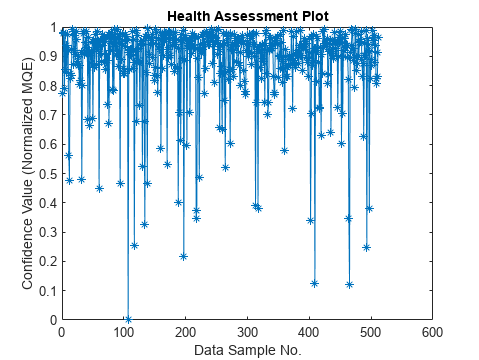

% Assuming predicted_labels_cat and actual_labels_cat are your categorical arrays from before

% Convert categorical to numeric for confusionmat
[~,~,actual_numeric] = unique(actual_labels_cat);
[~,~,predicted_numeric] = unique(predicted_labels_cat);

 % No x-tick labels needed as we're plotting a single value
% Assuming 'test_time_domain_features' contains your test data
numTestSamples = size(test_time_domain_features, 1); % Number of testing samples
MQEt = zeros(numTestSamples, 1); % Preallocate array for MQE values

for ii = 1:numTestSamples
    % Extract single test sample
    singleTestData = test_time_domain_features(ii, :);
    
    % Find BMU for the test sample
    bmu_index = som_bmus(sMap, singleTestData);
    bmu_vector = sMap.codebook(bmu_index, :); % Extract the BMU codebook vector
    
    % Calculate MQE value for each sample
    MQEt(ii) = norm(singleTestData - bmu_vector); % Euclidean distance
end

% Normalize MQE
MQEtn = 1 - (MQEt / max(MQEt)); % Normalize MQE values to fall between 0 and 1

%% Plot the calculated MQE values 
% This can help in observing the difference between normal condition and faulty conditions
figure; % Create a new figure window
plot(MQEtn, '-*');
xlabel('Data Sample No.');
ylabel('Confidence Value (Normalized MQE)');
title('Health Assessment Plot');

confMat = confusionmat(actual_labels_cell, predicted_labels);

% Initialize variables to store precision, recall, and F1 scores
numClasses = size(confMat, 1);
precision = zeros(numClasses, 1);
recall = zeros(numClasses, 1);
f1Scores = zeros(numClasses, 1);

% Calculate precision, recall, and F1 score for each class
for i = 1:numClasses
    truePositives = confMat(i, i);
    falsePositives = sum(confMat(:, i)) - truePositives;
    falseNegatives = sum(confMat(i, :)) - truePositives;
    
    precision(i) = truePositives / (truePositives + falsePositives);
    recall(i) = truePositives / (truePositives + falseNegatives);
    
    % Handle division by zero for precision and recall
    if precision(i) == 0 && recall(i) == 0
        f1Scores(i) = 0;
    else
        f1Scores(i) = 2 * ((precision(i) * recall(i)) / (precision(i) + recall(i)));
    end
end

% Display results
disp('Class | Precision | Recall | F1 Score');

Class | Precision | Recall | F1 Score


for i = 1:numClasses
    fprintf('%s: %.2f | %.2f | %.2f\n', label_names{i}, precision(i), recall(i), f1Scores(i));
end

normal: 0.98 | 0.98 | 0.98
roller: 1.00 | 1.00 | 1.00
inner: 1.00 | 1.00 | 1.00
outer: 1.00 | 1.00 | 1.00
inner+roller: 1.00 | 1.00 | 1.00
outer+inner: 0.94 | 0.92 | 0.93
outer+inner+roller: 0.98 | 0.98 | 0.98
outer+roller: 0.92 | 0.94 | 0.93
